# Initialize

foggy_imgs = Read_Images('images/restoration', 'foggy*.jpg');

Reading images at - images\restoration\foggy*.jpg
Number of images found in directory: 2
Read 2/2


manuscript_imgs = Read_Images('images/restoration', 'Voynich*.jpg');

Reading images at - images\restoration\Voynich*.jpg
Number of images found in directory: 2
Read 2/2


## Document - Denoise

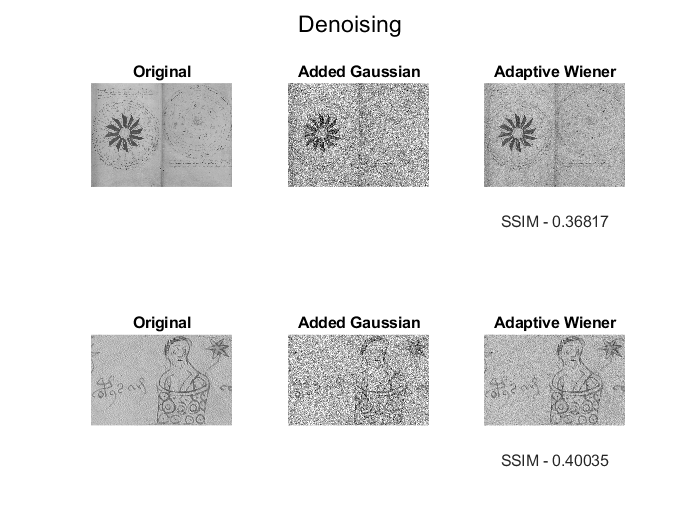

figure;
j = 1;
for i=1 : length(manuscript_imgs)
    img = manuscript_imgs{i};
    img_gray = rgb2gray(img);
    
    % simulate noise
    noise = 0.025;
    noisy_img = imnoise(img_gray, 'gaussian', 0, noise);
    
    % Adaptive Wiener Filter
    wnrAdapt_img = wiener2(noisy_img, [3,3], noise);
    
    subplot(2, 3, j); imshow(img_gray); title("Original");
    subplot(2, 3, j + 1); imshow(noisy_img); title("Added Gaussian");
    subplot(2, 3, j + 2); imshow(wnrAdapt_img); title("Adaptive Wiener"); xlabel("SSIM - " + ssim(wnrAdapt_img, img_gray));
    j = j + 3;
end
sgtitle("Denoising");

## Document - Deblur

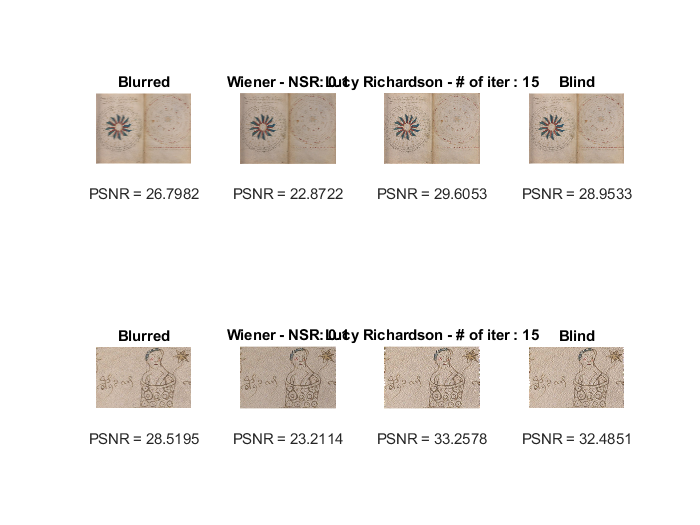

Elapsed time is 0.177465 seconds.


Elapsed time is 3.218482 seconds.


Elapsed time is 0.864112 seconds.


Elapsed time is 18.751450 seconds.


figure;
j = 1;
for i=1 : length(manuscript_imgs)
    img = manuscript_imgs{i};
    
    % simulate blur
    PSF_motion = fspecial('motion', 21, 11);
    PSF_gaussian = fspecial("gaussian", 5, 5);
    
    blurred_img = imfilter(img, PSF_motion, "symmetric", "conv");
    
    % Wiener Restoration Filter
    nsr = 0.1;
    tic;
    wnrAdapt_img = deconvwnr(blurred_img, PSF_motion, nsr);
    toc;
    
    % Lucy Richardson Method
    nr_iter = 15;
    tic;
    lucy_img = deconvlucy(blurred_img, PSF_motion, nr_iter);
    toc;
    
    % Blind Deconvolution
    blind_img = deconvblind(blurred_img, PSF_motion);
    
    subplot(2, 5, j); imshow(img); title("Original");
    
    subplot(2, 5, j + 1); imshow(blurred_img); title("Blurred");
    xlabel("PSNR = " + psnr(blurred_img, img));
    
    subplot(2, 5, j + 2); imshow(wnrAdapt_img); title("Wiener - NSR: " + nsr);
    xlabel("SSIM - " + ssim(wnrAdapt_img, img_gray));
    
    subplot(2, 5, j + 3); imshow(lucy_img); title("Lucy Richardson - # of iter : " + nr_iter);
    xlabel("SSIM - " + ssim(lucy_img, img_gray));
    
    subplot(2, 5, j + 4); imshow(blind_img); title("Blind");
    xlabel("SSIM - " + ssim(blind_img, img_gray));
    
    j = j + 4;
end

% Wiener makes the image darker the higher noise to signal ratio passed
% Lucy gives better, more deblurred results (increased psnr -> signal to noise ratio)

% Wiener takes significantly less time than Lucy's
%  Wiener:  2/3 sec
%  Lucy:    14 sec

## Fog - Haze Reduction

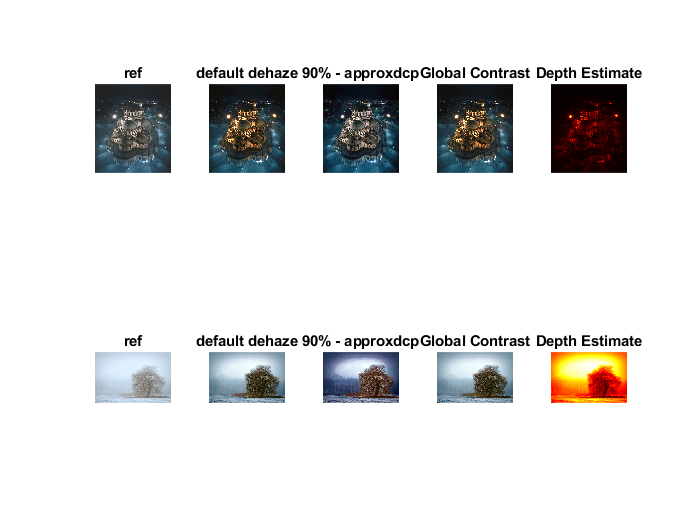

figure;
j = 1;
for i=1 : length(foggy_imgs)
    img = foggy_imgs{i};
   
    dehazed_img = imreducehaze(img);
    approx_img = imreducehaze(img, 0.9, 'Method',"approxdcp");
    
    con_img = imreducehaze(img, 1, "ContrastEnhancement","global");
    
    % Estimate haze thickness and image depth
    [~,h_thickness] = imreducehaze(img);
    img_depth = -log(1-h_thickness+eps);
    
    subplot(2, 5, j); imshow(img); title("ref");
    subplot(2, 5, j+1); imshow(dehazed_img); title("default dehaze");
    subplot(2, 5, j+2); imshow(approx_img); title("90% - approxdcp");
    subplot(2, 5, j+3); imshow(con_img); title("Global Contrast");
    subplot(2, 5, j+4); imshow(img_depth,[]); title("Depth Estimate"); colormap hot;
    j = j + 5;
end

% Questions %

% 1. Document restoration:
%   a. Explain the steps you took to denoise the images. Did you have to apply deblurring? If so, explain how you chose the PSF.

    % I used the adaptive wiener filter to denoise the image using a gaussian type PSF.
    % I also blurred and deblurred the image using a motion PSF, using the
    % Wiener restoration filter, Lucy Richardson and Blind deconvolution.

% 2. Fog removal:
%   a. Try out the in-built haze reduction of Matlab.
%   b. Perform one other enhancement technique of your choice and compare with (a).

% 3. When would this algorithm fail? Reflect on your achievement.

    % It would fail when an image has both under and over-exposed parts,
    % as it would always end up with sacrificing one of the areas' quality.